# Comparison of step responses

**Real system step response VS simulated step response woth real systems gains**

## INIT of PD-controller info

% clear
% clc

% PD-controller gains for pan & tilt
Kp_pan = 3;
Kd_pan = 0.9;

Kp_tilt = 1;
Kd_tilt = 0.09;

Ki = 0;

% Other init info
fs = 1000;  % Sampling frequency
ts = 1/fs; % Sampling time
N = 20;   % Filter order

## Transfer function setup

s = tf('s');

% Defining variables for transfer function
k_tilt_avg  = 1.73;     % DC-gain rps/V (rounds per second / Volts)
k_pan_avg   = 1.84;     % DC-gain rps/V (rounds per second / Volts)
tau_tilt    = 0.00575;   % Time constant (63.2%)
tau_pan     = 0.00591;   % Time constant (63.2%)

% Transfer functions
Gs_tilt = k_tilt_avg / ( (tau_tilt*s + 1) * s );
Gs_pan  = k_pan_avg  / ( (tau_pan*s  + 1) * s  );

% Extracting numerator and denominator from pan/tilt transfer functions
[Num_tilt, Den_tilt] = tfdata(Gs_tilt, 'v');
[Num_pan,  Den_pan]  = tfdata(Gs_pan,  'v');

%%% Creating Closed Loop system with PDF-controller %%%
PDF_pan = Kp_pan + Ki * (1/s) + Kd_pan * ( N/(1 + N * (1/s)) );
PDF_tilt = Kp_tilt + Ki * (1/s) + Kd_tilt * ( N/(1 + N * (1/s)) );
CL_pan = feedback(PDF_pan*Gs_pan,1);    % Pan closed loop
CL_tilt = feedback(PDF_tilt*Gs_tilt,1);  % Tilt closed loop

## Pan closed loop system comparison step responses with real system gains

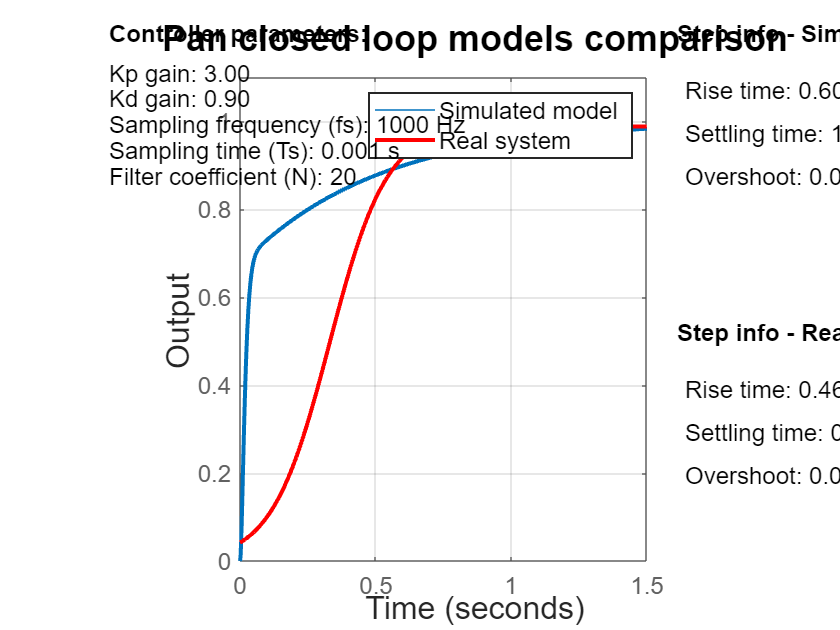

%%% PAN CLOSED LOOP STEP RESPONSE %%%
figure;
% Left: Step response
subplot(2,6,[2 3 4 5 8 9 10 11]);
step(CL_pan), grid on;
hold on
plot(t, y_fit, 'r')    % Sigmoid fitted model for step response
set(findall(gcf, 'Type', 'Line'), 'LineWidth', 2);
set(findall(gca, 'Type', 'Axes'), 'FontSize', 12);
xlabel('Time', 'FontSize', 16);
ylabel('Output', 'FontSize', 16);
xlim([0 1.5]);
ylim([0 1.1])
title('Pan closed loop models comparison', 'FontSize', 18);
lgd_pan = legend('Simulated model', 'Real system');
lgd_pan.FontSize = 12;       % Change font size
lgd_pan.LineWidth = 1;     % Change the box border line width
% Right: Step info text for simulated model with real system gains
info_pan_sim = stepinfo(CL_pan);
subplot(2,6,6);
set(title('Step info - Simulated model (BLUE):', 'FontSize', 12), 'Units', 'normalized', 'Position', [0 1 0], 'HorizontalAlignment', 'left');
axis off; % Hide axes
text(0.1, 0.8, sprintf('Rise time: %.3f s', info_pan_sim.RiseTime), 'FontSize', 12);
text(0.1, 0.6, sprintf('Settling time: %.3f s', info_pan_sim.SettlingTime), 'FontSize', 12);
text(0.1, 0.4, sprintf('Overshoot: %.2f %%', info_pan_sim.Overshoot), 'FontSize', 12);
% RIGHT: Step info text for real system
subplot(2,6,12);
info_pan_real = stepinfo(y_fit, t, 'RiseTimeLimits', [0.1 0.9]);
set(title('Step info - Real system (RED):', 'FontSize', 12), 'Units', 'normalized', 'Position', [0 1 0], 'HorizontalAlignment', 'left');
axis off; % Hide axes
text(0.1, 0.8, sprintf('Rise time: %.3f s', info_pan_real.RiseTime), 'FontSize', 12);
text(0.1, 0.6, sprintf('Settling time: %.3f s', info_pan_real.SettlingTime), 'FontSize', 12);
text(0.1, 0.4, sprintf('Overshoot: %.2f %%', info_pan_real.Overshoot), 'FontSize', 12);
% LEFT: Controller parameters text
subplot(2,6,[1 7]);
set(title('Controller parameters:', 'FontSize', 12), 'Units', 'normalized', 'Position', [0 1 0], 'HorizontalAlignment', 'left');
axis off; % Hide axes
text(0.0, 0.95, sprintf('Kp gain: %.2f %', Kp_pan), 'FontSize', 12);
text(0.0, 0.9, sprintf('Kd gain: %.2f %', Kd_pan), 'FontSize', 12);
text(0.0, 0.85, sprintf('Sampling frequency (fs): %.f Hz%', fs), 'FontSize', 12);
text(0.0, 0.8, sprintf('Sampling time (Ts): %.3f s%', ts), 'FontSize', 12);
text(0.0, 0.75, sprintf('Filter coefficient (N): %.f %', N), 'FontSize', 12);
hold off

## Tilt closed loop system comparison step responses with real system gains

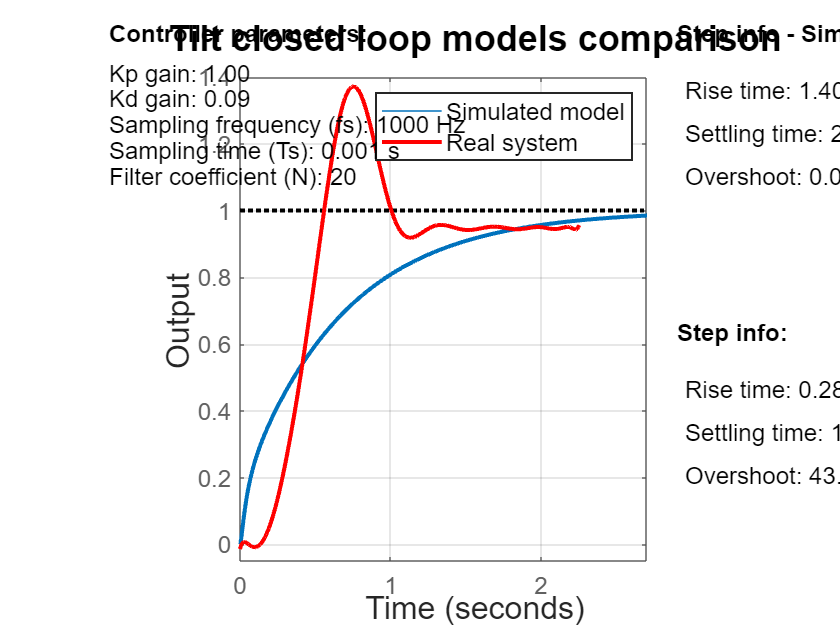

%%% TILT CLOSED LOOP STEP RESPONSE %%%
figure;
% Left: Step response
subplot(2,6,[2 3 4 5 8 9 10 11]);
step(CL_tilt), grid on;
hold on
plot(t_sim, y_poly, 'r-', 'LineWidth', 2), grid on;
set(findall(gcf, 'Type', 'Line'), 'LineWidth', 2);
set(findall(gca, 'Type', 'Axes'), 'FontSize', 12);
xlabel('Time', 'FontSize', 16);
ylabel('Output', 'FontSize', 16);
xlim([0 2.7]);
ylim([-0.05 1.4])
title('Tilt closed loop models comparison', 'FontSize', 18);
lgd_pan = legend('Simulated model', 'Real system');
lgd_pan.FontSize = 12;       % Change font size
lgd_pan.LineWidth = 1;     % Change the box border line width
% Right: Step info text for simulated model with real system gains
info_tilt_sim = stepinfo(CL_tilt);
subplot(2,6,6);
set(title('Step info - Simulated model (BLUE):', 'FontSize', 12), 'Units', 'normalized', 'Position', [0 1 0], 'HorizontalAlignment', 'left');
axis off; % Hide axes
text(0.1, 0.8, sprintf('Rise time: %.3f s', info_tilt_sim.RiseTime), 'FontSize', 12);
text(0.1, 0.6, sprintf('Settling time: %.3f s', info_tilt_sim.SettlingTime), 'FontSize', 12);
text(0.1, 0.4, sprintf('Overshoot: %.2f %%', info_tilt_sim.Overshoot), 'FontSize', 12);
% RIGHT: Step info text for real system
subplot(2,6,12);
set(title('Step info:', 'FontSize', 12), 'Units', 'normalized', 'Position', [0 1 0], 'HorizontalAlignment', 'left');
axis off; % Hide axes
text(0.1, 0.8, sprintf('Rise time: %.3f s', rise_time), 'FontSize', 12);
text(0.1, 0.6, sprintf('Settling time: %.3f s', settling_time), 'FontSize', 12);
text(0.1, 0.4, sprintf('Overshoot: %.2f %%', overshoot), 'FontSize', 12);
% LEFT: Controller parameters text
subplot(2,6,[1 7]);
set(title('Controller parameters:', 'FontSize', 12), 'Units', 'normalized', 'Position', [0 1 0], 'HorizontalAlignment', 'left');
axis off; % Hide axes
text(0.0, 0.95, sprintf('Kp gain: %.2f %', Kp_tilt), 'FontSize', 12);
text(0.0, 0.9, sprintf('Kd gain: %.2f %', Kd_tilt), 'FontSize', 12);
text(0.0, 0.85, sprintf('Sampling frequency (fs): %.f Hz%', fs), 'FontSize', 12);
text(0.0, 0.8, sprintf('Sampling time (Ts): %.3f s%', ts), 'FontSize', 12);
text(0.0, 0.75, sprintf('Filter coefficient (N): %.f %', N), 'FontSize', 12);
hold off